Introducción al Modelado Espacial de Robots

Resumen

%{


syms Tij(x_i_j,y_i_j,z_i_j,gi_j,bi_j,ai_j)

% Homogeneous transform
Tij(x_i_j,y_i_j,z_i_j,gi_j,bi_j,ai_j) = [cos(ai_j)*cos(bi_j) cos(ai_j)*sin(bi_j)*sin(gi_j)-sin(ai_j)*cos(gi_j) sin(ai_j)*sin(gi_j)+cos(ai_j)*sin(bi_j)*cos(gi_j) x_i_j; sin(ai_j)*cos(bi_j) cos(ai_j)*cos(gi_j)+sin(ai_j)*sin(bi_j)*sin(gi_j) sin(ai_j)*sin(bi_j)*cos(gi_j)-cos(ai_j)*sin(gi_j) y_i_j; -sin(bi_j) cos(bi_j)*sin(gi_j) cos(bi_j)*cos(gi_j) z_i_j; 0 0 0 1]

## Modelado de la posición del robot 3R

syms z_O_1 z_1_2 z_2_3 z_3_P  %parametros
syms theta_O_1 theta_1_2 theta_2_3 %grados de libertad

T_O_1 = Tij(0,0,z_O_1,0,0,theta_O_1)
T_1_2 = Tij(0,0,z_1_2,0,theta_1_2,0)
T_2_3 = Tij(0,0,z_2_3,0,theta_2_3,0)
T_3_P = Tij(0,0,z_3_P,0,0,0)

T_O_P = simplify(T_O_1*T_1_2*T_2_3*T_3_P)

Vector de postura

xi_O_P = [T_O_P(1,4); T_O_P(2,4); T_O_P(3,4); T_O_P(1,1); T_O_P(2,2); T_O_P(3,3)]

p_O_P = [T_O_P(1,4); T_O_P(2,4); T_O_P(3,4)]

## Modelo cinemático directo de las velocidades

Calculo del Jacobino


%J_theta = simplify(jacobian(xi_O_P,[theta_O_1,theta_1_2, theta_2_3]))
J_theta = simplify(jacobian(p_O_P, [theta_O_1, theta_1_2, theta_2_3]));

det(J_theta)

### Modelo cinemático inverso de las velocidades

%J_theta_psin = pinv(J_theta)

Modelo dinámico del robot en el espacio

Calculo de los centros de masa de los eslabones

syms theta_dot_O_1 theta_dot_1_2 theta_dot_2_3 z_1_C1 z_2_C2 z_3_C3

T_1_C1 = Tij(0,0,z_1_C1,0,0,0)

T_O_C1 = simplify(T_O_1*T_1_C1);

p_O_C1 = [T_O_C1(1,4); T_O_C1(2,4); T_O_C1(3,4)]

v_O_C1 = diff(p_O_C1, theta_O_1)*theta_dot_O_1 
%

T_2_C2 = Tij(0,0,z_2_C2,0,0,0)

T_O_C2 = simplify(T_O_1*T_1_2*T_2_C2);

p_O_C2 = [T_O_C2(1,4); T_O_C2(2,4); T_O_C2(3,4)]

v_O_C2 = diff(p_O_C2, theta_O_1)*theta_dot_O_1 + diff(p_O_C2, theta_1_2)*theta_dot_1_2

%

T_3_C3 = Tij(0,0,z_3_C3,0,0,0)

T_O_C3 = simplify(T_O_1*T_1_2*T_2_3*T_3_C3);

p_O_C3 = [T_O_C3(1,4); T_O_C3(2,4); T_O_C3(3,4)]

v_O_C3 = diff(p_O_C3, theta_O_1)*theta_dot_O_1 + diff(p_O_C3, theta_1_2)*theta_dot_1_2 + diff(p_O_C3, theta_2_3)*theta_dot_2_3


Calculo de la propagación de las velocidades angulares

% Matrices de Rotación

R_O_1 = [T_O_1(1,1),T_O_1(1,2),T_O_1(2,3); T_O_1(2,1),T_O_1(1,2),T_O_1(2,3);T_O_1(3,1),T_O_1(3,2),T_O_1(3,3)];
R_1_O = transpose(R_O_1)

R_1_2 = [T_1_2(1,1),T_1_2(1,2),T_1_2(2,3); T_1_2(2,1),T_1_2(1,2),T_1_2(2,3);T_1_2(3,1),T_1_2(3,2),T_1_2(3,3)];
R_2_1 = transpose(R_1_2)

R_2_3 = [T_2_3(1,1),T_2_3(1,2),T_2_3(2,3); T_2_3(2,1),T_2_3(1,2),T_2_3(2,3);T_2_3(3,1),T_2_3(3,2),T_2_3(3,3)];
R_3_2 = transpose(R_2_3)

% calculo de las velocidades angulares
omega_O_O = [0;0;0];
nu_1 = [0;0;1];
omega_1_1 = R_O_1*omega_O_O + nu_1*theta_dot_O_1

nu_2 = [0;1;0];
omega_2_2 = R_2_1*omega_1_1 + nu_2*theta_dot_1_2

nu_3 = [0;1;0];
omega_3_3 = R_3_2*omega_2_2 + nu_3*theta_dot_2_3

Matrices de inercia

syms I_xx1 I_yy1 I_zz1 I_xx2 I_yy2 I_zz2 I_xx3 I_yy3 I_zz3

I_C1 = [I_xx1, 0, 0; 0, I_yy1, 0; 0, 0, I_zz1]
I_C2 = [I_xx2, 0, 0; 0, I_yy2, 0; 0, 0, I_zz2]
I_C3 = [I_xx3, 0, 0; 0, I_yy3, 0; 0, 0, I_zz3]

Calculo del Lagrangeano

syms m_1 m_2 m_3 g

% energía cinetica
k_1 = 1/2*m_1*transpose(v_O_C1)*v_O_C1 + transpose(omega_1_1)*I_C1*omega_1_1
k_2 = 1/2*m_2*transpose(v_O_C2)*v_O_C2 + transpose(omega_2_2)*I_C2*omega_2_2
k_3 = 1/2*m_3*transpose(v_O_C3)*v_O_C3 + transpose(omega_3_3)*I_C3*omega_3_3

% energía potencial
g_O = [0;0;-g];

u_1 = -m_1*transpose(p_O_C1)*g_O
u_2 = -m_2*transpose(p_O_C2)*g_O
u_3 = -m_3*transpose(p_O_C3)*g_O

% lagrangeano

L = (k_1+k_2+k_3)-(u_1+u_2+u_3)

Calculo de los pares

syms theta_ddot_O_1 theta_ddot_1_2 theta_ddot_2_3

D_1 = diff(L,theta_dot_O_1)

tao_1 = (diff(D_1,theta_O_1)*theta_dot_O_1 + diff( ...
    D_1,theta_1_2)*theta_dot_1_2 + diff( ...
    D_1,theta_2_3)*theta_dot_2_3 + diff( ...
    D_1,theta_dot_O_1)*theta_ddot_O_1 + diff( ...
    D_1,theta_dot_1_2)*theta_ddot_1_2 + diff( ...
    D_1,theta_dot_2_3)*theta_ddot_2_3) - diff(L,theta_O_1)


D_2 = diff(L,theta_dot_1_2)
tao_2 = (diff(D_2,theta_O_1)*theta_dot_O_1 + diff( ...
    D_2,theta_1_2)*theta_dot_1_2 + diff( ...
    D_2,theta_2_3)*theta_dot_2_3 + diff( ...
    D_2,theta_dot_O_1)*theta_ddot_O_1 + diff( ...
    D_2,theta_dot_1_2)*theta_ddot_1_2 + diff( ...
    D_2,theta_dot_2_3)*theta_ddot_2_3) - diff(L,theta_1_2)

D_3 = diff(L,theta_dot_2_3)
tao_3 = (diff(D_3,theta_O_1)*theta_dot_O_1 + diff( ...
    D_3,theta_1_2)*theta_dot_1_2 + diff( ...
    D_3,theta_2_3)*theta_dot_2_3 + diff( ...
    D_3,theta_dot_O_1)*theta_ddot_O_1 + diff( ...
    D_3,theta_dot_1_2)*theta_ddot_1_2 + diff( ...
    D_3,theta_dot_2_3)*theta_ddot_2_3) - diff(L,theta_2_3)




% Vector de par

tau = collect([tao_1; tao_2; tao_3],[m_1,m_2,m_3, theta_ddot_O_1,theta_ddot_1_2,theta_ddot_2_3])


M_1 = subs(tau,[theta_ddot_O_1, theta_ddot_1_2, theta_ddot_2_3,theta_dot_O_1, theta_dot_1_2, theta_dot_2_3,g],[1, 0, 0,0, 0, 0,0])
M_2 = subs(tau,[theta_ddot_O_1, theta_ddot_1_2, theta_ddot_2_3,theta_dot_O_1, theta_dot_1_2, theta_dot_2_3,g],[0, 1, 0,0, 0, 0,0])
M_3 = subs(tau,[theta_ddot_O_1, theta_ddot_1_2, theta_ddot_2_3,theta_dot_O_1, theta_dot_1_2, theta_dot_2_3,g],[0, 0, 1,0, 0, 0,0])

M_q = collect([M_1 M_2 M_3],[m_1,m_2,m_3])


V_q = subs(tau,[theta_ddot_O_1, theta_ddot_1_2, theta_ddot_2_3,theta_dot_O_1, theta_dot_1_2, theta_dot_2_3,g],[0, 0, 0,theta_dot_O_1, theta_dot_1_2, theta_dot_2_3,0])
G_q = subs(tau,[theta_ddot_O_1, theta_ddot_1_2, theta_ddot_2_3,theta_dot_O_1, theta_dot_1_2, theta_dot_2_3,g],[0, 0, 0,0, 0, 0,g])
%}

# Datos del robot obtenidos de Inventor

clear; clc; close all;

%% Variables simbólicas del robot 3R

syms q1 q2 q3 real
syms dq1 dq2 dq3 real
syms ddq1 ddq2 ddq3 real

q = [q1; q2; q3];
dq = [dq1; dq2; dq3];
ddq = [ddq1; ddq2; ddq3];

%% Gravedad

g = 9.81; % m/s^2

%% Masas reales obtenidas de Inventor

m1 = 0.214; % kg - cintura
m2 = 0.448; % kg - brazo vertical
m3 = 0.304; % kg - brazo horizontal + pinza

%% Centros de masa absolutos obtenidos de Inventor
% Coordenadas en metros

rC1_abs = [
    0.007316;
   -0.012220;
    0.067155
];

rC2_abs = [
    0.007415;
   -0.010549;
    0.205414
];

rC3_abs = [
    0.007799849;
   -0.161106668;
    0.326759046
];

%% Posiciones de las articulaciones en Inventor
% Coordenadas en metros

rJ1_abs = [
    0.007316;
   -0.012207;
    0.045191
];

rJ2_abs = [
    0.007316;
   -0.012207;
    0.085000
];

rJ3_abs = [
    0.007316;
   -0.039207;
    0.322000
];

rP_abs = [
    0.007316;
   -0.255207;
    0.322000
];

%% Centros de masa relativos a cada articulación

rC1 = rC1_abs - rJ1_abs;
rC2 = rC2_abs - rJ2_abs;
rC3 = rC3_abs - rJ3_abs;

%% Inercias respecto al centro de gravedad
% kg*m^2

IC1 = [
    0.000068001   -0.000000484   -0.000000060;
   -0.000000484    0.000165953   -0.000000033;
   -0.000000060   -0.000000033    0.000137221
];

IC2 = [
    0.002115146    0.000000011    0.000000053;
    0.000000011    0.002204573    0.000008439;
    0.000000053    0.000008439    0.000142491
];

IC3 = [
    0.002391018    0.000009703    0.000000681;
    0.000009703    0.000062846    0.000068461;
    0.000000681    0.000068461    0.002397553
];

%% Distancias entre articulaciones

z12 = rJ2_abs(3) - rJ1_abs(3);

y23 = rJ3_abs(2) - rJ2_abs(2);
z23 = rJ3_abs(3) - rJ2_abs(3);

y3P = rP_abs(2) - rJ3_abs(2);
z3P = rP_abs(3) - rJ3_abs(3);

%% Verificación

m_movil = m1 + m2 + m3

m_movil = 0.9660


rC1

rC1 =          0
   -0.0000
    0.0220


rC2

rC2 =     0.0001
    0.0017
    0.1204


rC3

rC3 =     0.0005
   -0.1219
    0.0048



z12

z12 = 0.0398

y23

y23 = -0.0270

z23

z23 = 0.2370

y3P

y3P = -0.2160

z3P

z3P = 0


%% Paso 2 - Cinemática directa del robot 3R

% El marco 0 se coloca en la articulación 1.
% Ejes reales:
% q1 gira alrededor de Z
% q2 gira alrededor de X
% q3 gira alrededor de X

RotZ = @(th) [
    cos(th)  -sin(th)   0   0;
    sin(th)   cos(th)   0   0;
    0         0         1   0;
    0         0         0   1
    ];

RotX = @(th) [
    1    0          0         0;
    0    cos(th)   -sin(th)  0;
    0    sin(th)    cos(th)  0;
    0    0          0        1
    ];

Trans = @(x,y,z) [
    1  0  0  x;
    0  1  0  y;
    0  0  1  z;
    0  0  0  1
    ];

%% Transformaciones homogéneas

T0_1 = RotZ(q1);

T1_2 = Trans(0, 0, z12) * RotX(q2);

T2_3 = Trans(0, y23, z23) * RotX(q3);

T3_P = Trans(0, y3P, z3P);

%% Transformaciones acumuladas

T0_2 = simplify(T0_1 * T1_2);
T0_3 = simplify(T0_2 * T2_3);
T0_P = simplify(T0_3 * T3_P);

%% Posición del efector final respecto a J1

pP = simplify(T0_P(1:3,4));

disp('Posición simbólica del efector final:')

Posición simbólica del efector final:


pP

$$pP = \begin{array}{l} \left(\begin{array}{c} \frac{3\,\sin\left(q_{1}\right)\,\sigma_{1}}{1000}\\ -\frac{3\,\cos\left(q_{1}\right)\,\sigma_{1}}{1000}\\ \frac{237\,\cos\left(q_{2}\right)}{1000}-\frac{27\,\sin\left(q_{2}+q_{3}\right)}{125}-\frac{27\,\sin\left(q_{2}\right)}{1000}+\frac{5737081522111747}{144115188075855872} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=72\,\cos\left(q_{2}+q_{3}\right)+9\,\cos\left(q_{2}\right)+79\,\sin\left(q_{2}\right) \end{array}$$


%%% Verificación con q1 = q2 = q3 = 0

pP_cero = simplify(subs(pP, [q1 q2 q3], [0 0 0]));

disp('Posición del efector final con q = 0, respecto a J1:')

Posición del efector final con q = 0, respecto a J1:


pP_cero_dec = double(vpa(pP_cero, 8))

pP_cero_dec =          0
   -0.2430
    0.2768



disp('Posición absoluta del efector final con q = 0:')

Posición absoluta del efector final con q = 0:


pP_abs_cero = rJ1_abs + pP_cero;
pP_abs_cero_dec = double(vpa(pP_abs_cero, 8))

pP_abs_cero_dec =     0.0073
   -0.2552
    0.3220


%% Paso 3 - Posiciones de los centros de masa

% Centro de masa del eslabón 1 respecto a J1
pC1_h = T0_1 * [rC1; 1];
pC1 = simplify(pC1_h(1:3));

% Centro de masa del eslabón 2 respecto a J1
pC2_h = T0_2 * [rC2; 1];
pC2 = simplify(pC2_h(1:3));

% Centro de masa del eslabón 3 respecto a J1
pC3_h = T0_3 * [rC3; 1];
pC3 = simplify(pC3_h(1:3));

disp('Centro de masa 1 respecto a J1:')

Centro de masa 1 respecto a J1:


pC1

$$pC1 = \left(\begin{array}{c} \frac{936748722493\,\sin\left(q_{1}\right)}{72057594037927936}\\ -\frac{936748722493\,\cos\left(q_{1}\right)}{72057594037927936}\\ \frac{3165345990898099}{144115188075855872} \end{array}\right)$$


disp('Centro de masa 2 respecto a J1:')

Centro de masa 2 respecto a J1:


pC2

$$pC2 = \left(\begin{array}{c} \frac{57069614478039\,\cos\left(q_{1}\right)}{576460752303423488}-\frac{955771927319077\,\cos\left(q_{2}\right)\,\sin\left(q_{1}\right)}{576460752303423488}+\frac{8676743128483055\,\sin\left(q_{1}\right)\,\sin\left(q_{2}\right)}{72057594037927936}\\ \frac{57069614478039\,\sin\left(q_{1}\right)}{576460752303423488}+\frac{955771927319077\,\cos\left(q_{1}\right)\,\cos\left(q_{2}\right)}{576460752303423488}-\frac{8676743128483055\,\cos\left(q_{1}\right)\,\sin\left(q_{2}\right)}{72057594037927936}\\ \frac{8676743128483055\,\cos\left(q_{2}\right)}{72057594037927936}+\frac{955771927319077\,\sin\left(q_{2}\right)}{576460752303423488}+\frac{5737081522111747}{144115188075855872} \end{array}\right)$$


disp('Centro de masa 3 respecto a J1:')

Centro de masa 3 respecto a J1:


pC3

$$pC3 = \begin{array}{l} \left(\begin{array}{c} \frac{557839917082519\,\cos\left(q_{1}\right)}{1152921504606846976}+\frac{3\,\sin\left(q_{1}\right)\,\sigma_{1}}{1000}+\frac{2195949197525549\,\cos\left(q_{2}+q_{3}\right)\,\sin\left(q_{1}\right)}{18014398509481984}+\frac{21432837792239\,\sin\left(q_{2}+q_{3}\right)\,\sin\left(q_{1}\right)}{4503599627370496}\\ \frac{557839917082519\,\sin\left(q_{1}\right)}{1152921504606846976}-\frac{3\,\cos\left(q_{1}\right)\,\sigma_{1}}{1000}-\frac{2195949197525549\,\cos\left(q_{2}+q_{3}\right)\,\cos\left(q_{1}\right)}{18014398509481984}-\frac{21432837792239\,\sin\left(q_{2}+q_{3}\right)\,\cos\left(q_{1}\right)}{4503599627370496}\\ \frac{21432837792239\,\cos\left(q_{2}+q_{3}\right)}{4503599627370496}-\frac{2195949197525549\,\sin\left(q_{2}+q_{3}\right)}{18014398509481984}+\frac{237\,\cos\left(q_{2}\right)}{1000}-\frac{27\,\sin\left(q_{2}\right)}{1000}+\frac{5737081522111747}{144115188075855872} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=9\,\cos\left(q_{2}\right)+79\,\sin\left(q_{2}\right) \end{array}$$


%% Verificación con q1 = q2 = q3 = 0

pC1_cero = double(vpa(subs(pC1, [q1 q2 q3], [0 0 0]), 8));
pC2_cero = double(vpa(subs(pC2, [q1 q2 q3], [0 0 0]), 8));
pC3_cero = double(vpa(subs(pC3, [q1 q2 q3], [0 0 0]), 8));

disp('Centros de masa relativos a J1 con q = 0:')

Centros de masa relativos a J1 con q = 0:


pC1_cero

pC1_cero =          0
   -0.0000
    0.0220


pC2_cero

pC2_cero =     0.0001
    0.0017
    0.1602


pC3_cero

pC3_cero =     0.0005
   -0.1489
    0.2816



disp('Centros de masa absolutos con q = 0:')

Centros de masa absolutos con q = 0:


pC1_abs_cero = double(vpa(rJ1_abs + pC1_cero, 8))

pC1_abs_cero =     0.0073
   -0.0122
    0.0672


pC2_abs_cero = double(vpa(rJ1_abs + pC2_cero, 8))

pC2_abs_cero =     0.0074
   -0.0105
    0.2054


pC3_abs_cero = double(vpa(rJ1_abs + pC3_cero, 8))

pC3_abs_cero =     0.0078
   -0.1611
    0.3268


%% Paso 4 - Jacobianos y velocidades

% Jacobianos lineales de cada centro de masa
Jv1 = simplify(jacobian(pC1, q));
Jv2 = simplify(jacobian(pC2, q));
Jv3 = simplify(jacobian(pC3, q));

% Velocidades lineales de los centros de masa
vC1 = simplify(Jv1 * dq);
vC2 = simplify(Jv2 * dq);
vC3 = simplify(Jv3 * dq);

%% Ejes de rotación de las articulaciones expresados en el marco base

% Joint 1 gira alrededor de Z
z0 = [0; 0; 1];

% Joint 2 gira alrededor de X después de q1
x1 = simplify(T0_1(1:3,1:3) * [1; 0; 0]);

% Joint 3 gira alrededor de X después de q1 y q2
x2 = simplify(T0_2(1:3,1:3) * [1; 0; 0]);

%% Velocidades angulares de cada eslabón

w1 = simplify(z0*dq1);

w2 = simplify(z0*dq1 + x1*dq2);

w3 = simplify(z0*dq1 + x1*dq2 + x2*dq3);

%% Mostrar resultados principales

disp('Jacobiano lineal del centro de masa 1:')

Jacobiano lineal del centro de masa 1:


Jv1

$$Jv1 = \left(\begin{array}{ccc} \frac{936748722493\,\cos\left(q_{1}\right)}{72057594037927936} & 0 & 0\\ \frac{936748722493\,\sin\left(q_{1}\right)}{72057594037927936} & 0 & 0\\ 0 & 0 & 0 \end{array}\right)$$


disp('Jacobiano lineal del centro de masa 2:')

Jacobiano lineal del centro de masa 2:


Jv2

$$Jv2 = \begin{array}{l} \left(\begin{array}{ccc} \frac{8676743128483055\,\cos\left(q_{1}\right)\,\sin\left(q_{2}\right)}{72057594037927936}-\frac{955771927319077\,\cos\left(q_{1}\right)\,\cos\left(q_{2}\right)}{576460752303423488}-\frac{57069614478039\,\sin\left(q_{1}\right)}{576460752303423488} & \frac{\sin\left(q_{1}\right)\,\sigma_{1}}{576460752303423488} & 0\\ \frac{57069614478039\,\cos\left(q_{1}\right)}{576460752303423488}-\frac{955771927319077\,\cos\left(q_{2}\right)\,\sin\left(q_{1}\right)}{576460752303423488}+\frac{8676743128483055\,\sin\left(q_{1}\right)\,\sin\left(q_{2}\right)}{72057594037927936} & -\frac{\cos\left(q_{1}\right)\,\sigma_{1}}{576460752303423488} & 0\\ 0 & \frac{955771927319077\,\cos\left(q_{2}\right)}{576460752303423488}-\frac{8676743128483055\,\sin\left(q_{2}\right)}{72057594037927936} & 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=69413945027864440\,\cos\left(q_{2}\right)+955771927319077\,\sin\left(q_{2}\right) \end{array}$$


disp('Jacobiano lineal del centro de masa 3:')

Jacobiano lineal del centro de masa 3:


Jv3

$$Jv3 = \begin{array}{l} \left(\begin{array}{ccc} \frac{3\,\cos\left(q_{1}\right)\,\sigma_{3}}{1000}-\frac{557839917082519\,\sin\left(q_{1}\right)}{1152921504606846976}+\frac{2195949197525549\,\cos\left(q_{2}+q_{3}\right)\,\cos\left(q_{1}\right)}{18014398509481984}+\frac{21432837792239\,\sin\left(q_{2}+q_{3}\right)\,\cos\left(q_{1}\right)}{4503599627370496} & \frac{\sin\left(q_{1}\right)\,\sigma_{1}}{2251799813685248000} & \frac{\sin\left(q_{1}\right)\,\sigma_{2}}{18014398509481984}\\ \frac{557839917082519\,\cos\left(q_{1}\right)}{1152921504606846976}+\frac{3\,\sin\left(q_{1}\right)\,\sigma_{3}}{1000}+\frac{2195949197525549\,\cos\left(q_{2}+q_{3}\right)\,\sin\left(q_{1}\right)}{18014398509481984}+\frac{21432837792239\,\sin\left(q_{2}+q_{3}\right)\,\sin\left(q_{1}\right)}{4503599627370496} & -\frac{\cos\left(q_{1}\right)\,\sigma_{1}}{2251799813685248000} & -\frac{\cos\left(q_{1}\right)\,\sigma_{2}}{18014398509481984}\\ 0 & -\sigma_{5}-\sigma_{4}-\frac{27\,\cos\left(q_{2}\right)}{1000}-\frac{237\,\sin\left(q_{2}\right)}{1000} & -\sigma_{5}-\sigma_{4} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=10716418896119500\,\cos\left(q_{2}+q_{3}\right)-274493649690693625\,\sin\left(q_{2}+q_{3}\right)+533676555843403776\,\cos\left(q_{2}\right)-60798594969501696\,\sin\left(q_{2}\right)\\ \sigma_{2}=85731351168956\,\cos\left(q_{2}+q_{3}\right)-2195949197525549\,\sin\left(q_{2}+q_{3}\right)\\ \sigma_{3}=9\,\cos\left(q_{2}\right)+79\,\sin\left(q_{2}\right)\\ \sigma_{4}=\frac{21432837792239\,\sin\left(q_{2}+q_{3}\right)}{4503599627370496}\\ \sigma_{5}=\frac{2195949197525549\,\cos\left(q_{2}+q_{3}\right)}{18014398509481984} \end{array}$$


disp('Velocidad angular del eslabón 1:')

Velocidad angular del eslabón 1:


w1

$$w1 = \left(\begin{array}{c} 0\\ 0\\ {\mathrm{dq}}_{1} \end{array}\right)$$


disp('Velocidad angular del eslabón 2:')

Velocidad angular del eslabón 2:


w2

$$w2 = \left(\begin{array}{c} {\mathrm{dq}}_{2}\,\cos\left(q_{1}\right)\\ {\mathrm{dq}}_{2}\,\sin\left(q_{1}\right)\\ {\mathrm{dq}}_{1} \end{array}\right)$$


disp('Velocidad angular del eslabón 3:')

Velocidad angular del eslabón 3:


w3

$$w3 = \left(\begin{array}{c} \cos\left(q_{1}\right)\,\left({\mathrm{dq}}_{2}+{\mathrm{dq}}_{3}\right)\\ \sin\left(q_{1}\right)\,\left({\mathrm{dq}}_{2}+{\mathrm{dq}}_{3}\right)\\ {\mathrm{dq}}_{1} \end{array}\right)$$


%% Verificación rápida con q = 0 y velocidades conocidas

vars_test = [q1 q2 q3 dq1 dq2 dq3];
vals_test = [0 0 0 0.1 0.2 0.3];

w1_test = double(vpa(subs(w1, vars_test, vals_test), 8))

w1_test =          0
         0
    0.1000


w2_test = double(vpa(subs(w2, vars_test, vals_test), 8))

w2_test =     0.2000
         0
    0.1000


w3_test = double(vpa(subs(w3, vars_test, vals_test), 8))

w3_test =     0.5000
         0
    0.1000



vC1_test = double(vpa(subs(vC1, vars_test, vals_test), 8))

vC1_test = 1.0e-05 *

    0.1300
         0
         0


vC2_test = double(vpa(subs(vC2, vars_test, vals_test), 8))

vC2_test =    -0.0002
   -0.0241
    0.0003


vC3_test = double(vpa(subs(vC3, vars_test, vals_test), 8))

vC3_test =     0.0149
   -0.0497
   -0.0663


%% Paso 5 - Energía cinética y energía potencial

% Matrices de rotación de cada eslabón respecto al marco base
R0_1 = T0_1(1:3,1:3);
R0_2 = T0_2(1:3,1:3);
R0_3 = T0_3(1:3,1:3);

% Inercias expresadas en el marco base
I01 = simplify(R0_1 * IC1 * R0_1.');
I02 = simplify(R0_2 * IC2 * R0_2.');
I03 = simplify(R0_3 * IC3 * R0_3.');

%% Energía cinética traslacional

Ktrans1 = simplify(1/2 * m1 * (vC1.' * vC1));
Ktrans2 = simplify(1/2 * m2 * (vC2.' * vC2));
Ktrans3 = simplify(1/2 * m3 * (vC3.' * vC3));

%% Energía cinética rotacional

Krot1 = simplify(1/2 * (w1.' * I01 * w1));
Krot2 = simplify(1/2 * (w2.' * I02 * w2));
Krot3 = simplify(1/2 * (w3.' * I03 * w3));

%% Energía cinética total

K1 = simplify(Ktrans1 + Krot1);
K2 = simplify(Ktrans2 + Krot2);
K3 = simplify(Ktrans3 + Krot3);

K = simplify(K1 + K2 + K3);

disp('Energía cinética total K:')

Energía cinética total K:


K


%% Energía potencial gravitacional
% Se usa la altura absoluta Z de cada centro de masa.

zC1_abs_q = rJ1_abs(3) + pC1(3);
zC2_abs_q = rJ1_abs(3) + pC2(3);
zC3_abs_q = rJ1_abs(3) + pC3(3);

U1 = simplify(m1 * g * zC1_abs_q);
U2 = simplify(m2 * g * zC2_abs_q);
U3 = simplify(m3 * g * zC3_abs_q);

U = simplify(U1 + U2 + U3);

disp('Energía potencial total U:')

Energía potencial total U:


U

$$U = \frac{399486663609542721\,\cos\left(q_{2}+q_{3}\right)}{28147497671065600000}-\frac{40930297092678707811\,\sin\left(q_{2}+q_{3}\right)}{112589990684262400000}+\frac{17395096707276845316489\,\cos\left(q_{2}\right)}{14073748835532800000000}-\frac{8245389364979824174077\,\sin\left(q_{2}\right)}{112589990684262400000000}+\frac{3115525680603264621934370400152463}{4056481920730334084789450257203200}$$


%% Lagrangiano

L = simplify(K - U);

disp('Lagrangiano L = K - U:')

Lagrangiano L = K - U:


L


%% Verificación numérica rápida

vars_test = [q1 q2 q3 dq1 dq2 dq3];
vals_test = [0 0 0 0.1 0.2 0.3];

K_test = double(vpa(subs(K, vars_test, vals_test), 8))

K_test = 0.0016

U_test = double(vpa(subs(U, vars_test, vals_test), 8))

U_test = 2.0182

L_test = double(vpa(subs(L, vars_test, vals_test), 8))

L_test = -2.0167

%% Paso 6 - Ecuaciones dinámicas por Lagrange

% Derivadas parciales del Lagrangiano

dL_dq = jacobian(L, q).';
dL_ddq = jacobian(L, dq).';

% Derivada total respecto al tiempo:
% d/dt(dL/ddq) = d/dq(dL/ddq)*dq + d/ddq(dL/ddq)*ddq

d_dt_dL_ddq = jacobian(dL_ddq, q) * dq + jacobian(dL_ddq, dq) * ddq;

% Torques generalizados

tau = simplify(d_dt_dL_ddq - dL_dq);

disp('Vector de torques tau:')

Vector de torques tau:


tau


%% Matriz de inercia M(q)

M_q = simplify(jacobian(tau, ddq));

disp('Matriz de inercia M(q):')

Matriz de inercia M(q):


M_q


%% Términos restantes: Coriolis, centrífugos y gravedad

h_q = simplify(tau - M_q * ddq);

% Vector de gravedad G(q)
G_q = simplify(subs(h_q, [dq1 dq2 dq3], [0 0 0]));

% Vector de términos de velocidad V(q,dq)
V_q = simplify(h_q - G_q);

disp('Vector de términos de velocidad V(q,dq):')

Vector de términos de velocidad V(q,dq):


V_q


disp('Vector de gravedad G(q):')

Vector de gravedad G(q):


G_q

$$G\_q = \left(\begin{array}{c} 0\\ -\frac{981\,\sqrt{20193781097668132986784901930709439522193}\,\cos\left(q_{2}-\mathrm{atan}\left(\frac{141856038387578758952}{8405085998960065417}\right)\right)}{112589990684262400000000}-\frac{18639\,\sqrt{4829542742686357471652165881337}\,\cos\left(q_{2}+q_{3}-\mathrm{atan}\left(\frac{85731351168956}{2195949197525549}\right)\right)}{112589990684262400000}\\ -\frac{18639\,\sqrt{4829542742686357471652165881337}\,\cos\left(q_{2}+q_{3}-\mathrm{atan}\left(\frac{85731351168956}{2195949197525549}\right)\right)}{112589990684262400000} \end{array}\right)$$


%% Verificación del modelo dinámico

% Debe cumplirse:
% tau = M(q)*ddq + V(q,dq) + G(q)

tau_verificacion = simplify(M_q * ddq + V_q + G_q);

disp('Verificación tau - tau_verificacion:')

Verificación tau - tau_verificacion:


verificacion = simplify(tau - tau_verificacion)

$$verificacion = \left(\begin{array}{c} 0\\ 0\\ 0 \end{array}\right)$$


%% Paso 7 - Evaluación numérica del modelo dinámico

% Postura de prueba en grados
q_test_deg = [0; 20; -25];

% Convertir a radianes
q_test = deg2rad(q_test_deg);

% Velocidades articulares de prueba, rad/s
dq_test = [
    0.10;
    0.20;
    0.10
    ];

% Aceleraciones articulares de prueba, rad/s^2
ddq_test = [
    0.05;
    0.02;
    -0.03
    ];

%% Variables para sustitución

vars_dyn = [
    q1 q2 q3 ...
    dq1 dq2 dq3 ...
    ddq1 ddq2 ddq3
    ];

vals_dyn = [
    q_test.' ...
    dq_test.' ...
    ddq_test.'
    ];

%% Evaluación numérica de M(q), V(q,dq), G(q) y tau

M_eval = double(vpa(subs(M_q, [q1 q2 q3], q_test.'), 8));

V_eval = double(vpa(subs(V_q, ...
    [q1 q2 q3 dq1 dq2 dq3], ...
    [q_test.' dq_test.']), 8));

G_eval = double(vpa(subs(G_q, [q1 q2 q3], q_test.'), 8));

tau_eval = double(vpa(subs(tau, vars_dyn, vals_dyn), 8));

%% Verificación usando tau = M*ddq + V + G

tau_reconstruida = M_eval * ddq_test + V_eval + G_eval;

error_tau = tau_eval - tau_reconstruida;

disp('Matriz de inercia evaluada M_eval:')

Matriz de inercia evaluada M_eval:


M_eval

M_eval =     0.0193   -0.0000   -0.0000
   -0.0000    0.0426    0.0118
   -0.0000    0.0118    0.0069



disp('Vector de velocidad evaluado V_eval:')

Vector de velocidad evaluado V_eval:


V_eval

V_eval = 1.0e-03 *

    0.7811
   -0.5556
    0.2809



disp('Vector de gravedad evaluado G_eval:')

Vector de gravedad evaluado G_eval:


G_eval

G_eval =          0
   -0.8525
   -0.3609



disp('Torque evaluado directamente tau_eval:')

Torque evaluado directamente tau_eval:


tau_eval

tau_eval =     0.0017
   -0.8525
   -0.3606



disp('Torque reconstruido M*ddq + V + G:')

Torque reconstruido M*ddq + V + G:


tau_reconstruida

tau_reconstruida =     0.0017
   -0.8525
   -0.3606



disp('Error entre ambos:')

Error entre ambos:


error_tau

error_tau = 1.0e-15 *

         0
    0.1110
         0


%% Paso 8 - Trayectoria articular y torques

% Trayectoria suave de reposo a reposo usando polinomio de 5to orden

tf = 5;          % tiempo total en segundos
N = 200;         % número de puntos
t = linspace(0, tf, N);

% Posición inicial y final en grados
q0_deg = [0; 0; 0];
qf_deg = [45; 25; -30];

% Convertir a radianes
q0 = deg2rad(q0_deg);
qf = deg2rad(qf_deg);

% Inicialización
Q = zeros(3,N);
DQ = zeros(3,N);
DDQ = zeros(3,N);
Tau = zeros(3,N);
Pot = zeros(3,N);
Pef = zeros(3,N);

% Crear funciones numéricas desde las expresiones simbólicas
tau_fun = matlabFunction(tau, ...
    'Vars', {q1, q2, q3, dq1, dq2, dq3, ddq1, ddq2, ddq3});

pP_fun = matlabFunction(pP, ...
    'Vars', {q1, q2, q3});

for i = 1:N

    r = t(i)/tf;

    % Polinomio 5to orden
    s = 10*r^3 - 15*r^4 + 6*r^5;
    ds = (30*r^2 - 60*r^3 + 30*r^4)/tf;
    dds = (60*r - 180*r^2 + 120*r^3)/tf^2;

    % Posición, velocidad y aceleración articular
    Q(:,i) = q0 + (qf - q0)*s;
    DQ(:,i) = (qf - q0)*ds;
    DDQ(:,i) = (qf - q0)*dds;

    % Variables articulares instantáneas
    qi = Q(:,i);
    dqi = DQ(:,i);
    ddqi = DDQ(:,i);

    % Torque dinámico
    Tau(:,i) = tau_fun( ...
        qi(1), qi(2), qi(3), ...
        dqi(1), dqi(2), dqi(3), ...
        ddqi(1), ddqi(2), ddqi(3));

    % Potencia por articulación
    Pot(:,i) = Tau(:,i).*DQ(:,i);

    % Posición del efector final absoluta
    Pef(:,i) = rJ1_abs + pP_fun(qi(1), qi(2), qi(3));
end

disp('Trayectoria calculada correctamente.')

Trayectoria calculada correctamente.


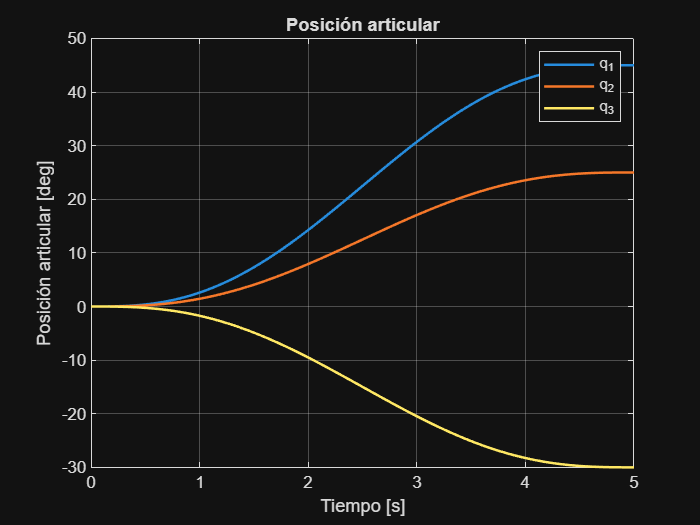

%% Paso 9 - Gráficas de posición, velocidad y aceleración articular

figure;
plot(t, rad2deg(Q(1,:)), 'LineWidth', 1.5); hold on;
plot(t, rad2deg(Q(2,:)), 'LineWidth', 1.5);
plot(t, rad2deg(Q(3,:)), 'LineWidth', 1.5);
grid on;
xlabel('Tiempo [s]');
ylabel('Posición articular [deg]');
title('Posición articular');
legend('q_1','q_2','q_3');

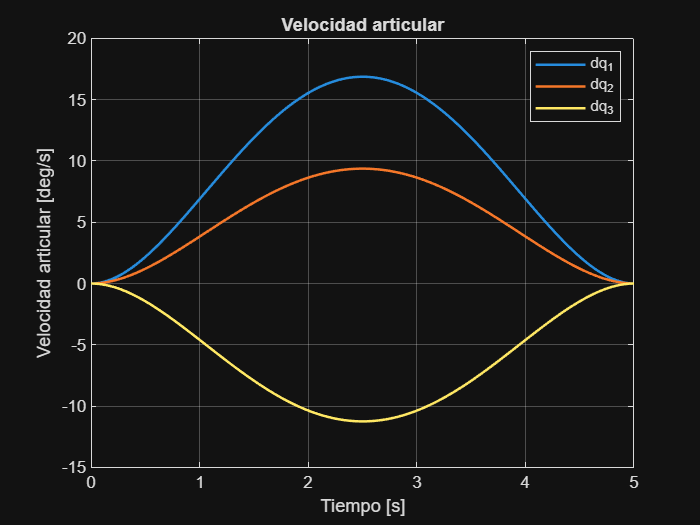


figure;
plot(t, rad2deg(DQ(1,:)), 'LineWidth', 1.5); hold on;
plot(t, rad2deg(DQ(2,:)), 'LineWidth', 1.5);
plot(t, rad2deg(DQ(3,:)), 'LineWidth', 1.5);
grid on;
xlabel('Tiempo [s]');
ylabel('Velocidad articular [deg/s]');
title('Velocidad articular');
legend('dq_1','dq_2','dq_3');

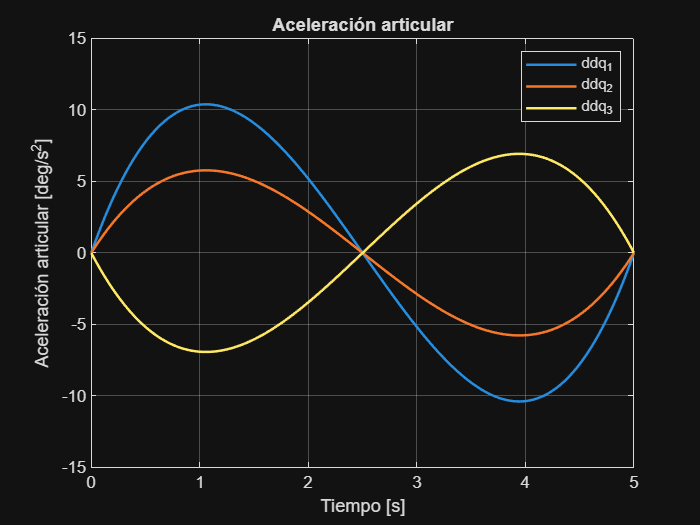


figure;
plot(t, rad2deg(DDQ(1,:)), 'LineWidth', 1.5); hold on;
plot(t, rad2deg(DDQ(2,:)), 'LineWidth', 1.5);
plot(t, rad2deg(DDQ(3,:)), 'LineWidth', 1.5);
grid on;
xlabel('Tiempo [s]');
ylabel('Aceleración articular [deg/s^2]');
title('Aceleración articular');
legend('ddq_1','ddq_2','ddq_3');

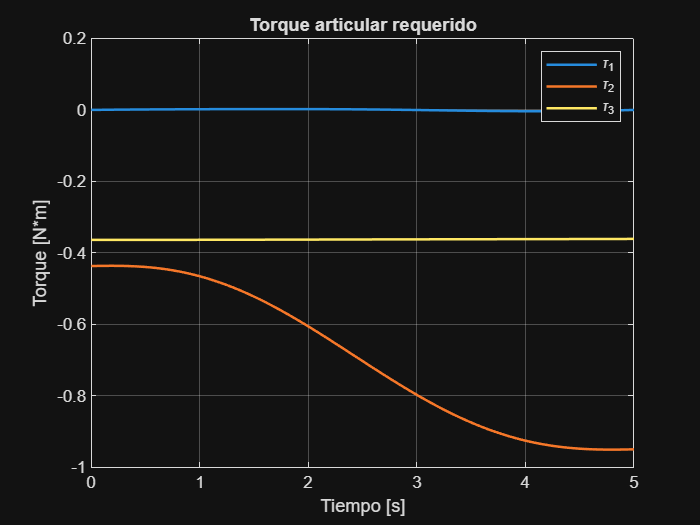

%% Paso 10 - Gráficas de torque y potencia

figure;
plot(t, Tau(1,:), 'LineWidth', 1.5); hold on;
plot(t, Tau(2,:), 'LineWidth', 1.5);
plot(t, Tau(3,:), 'LineWidth', 1.5);
grid on;
xlabel('Tiempo [s]');
ylabel('Torque [N*m]');
title('Torque articular requerido');
legend('\tau_1','\tau_2','\tau_3');

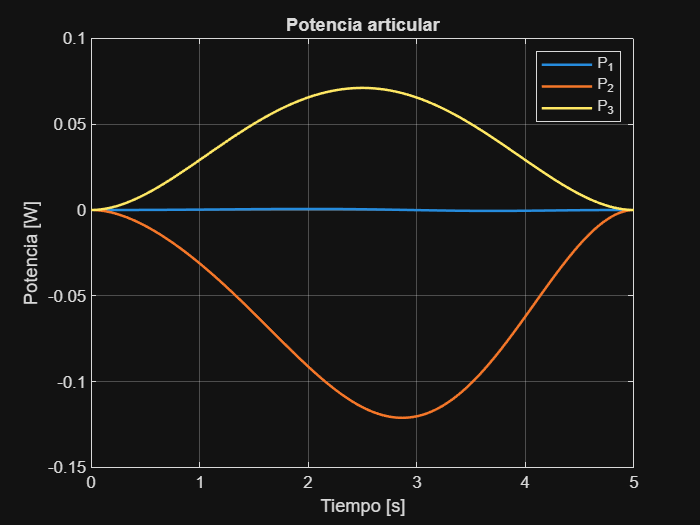


figure;
plot(t, Pot(1,:), 'LineWidth', 1.5); hold on;
plot(t, Pot(2,:), 'LineWidth', 1.5);
plot(t, Pot(3,:), 'LineWidth', 1.5);
grid on;
xlabel('Tiempo [s]');
ylabel('Potencia [W]');
title('Potencia articular');
legend('P_1','P_2','P_3');

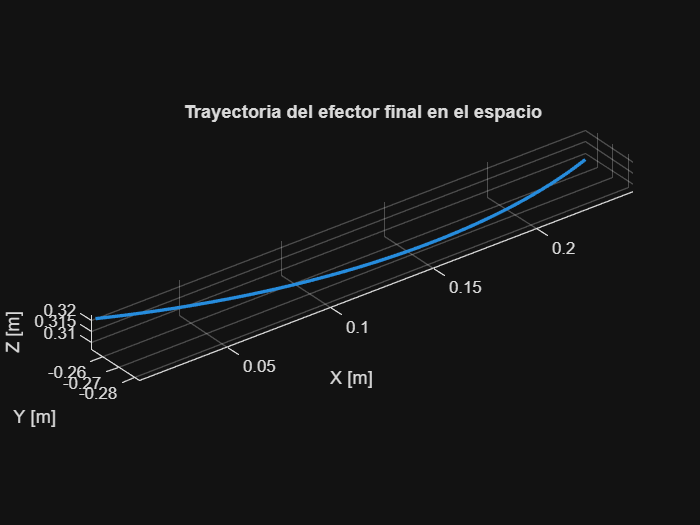

%% Paso 11 - Trayectoria del efector final

figure;
plot3(Pef(1,:), Pef(2,:), Pef(3,:), 'LineWidth', 2);
grid on;
xlabel('X [m]');
ylabel('Y [m]');
zlabel('Z [m]');
title('Trayectoria del efector final en el espacio');
axis equal;